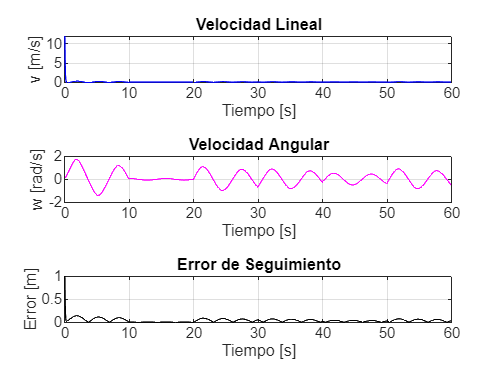

%% Trayectoria 1 - Hexágono
clearvars -except ts tf t N
close all; clc;

ts = 0.05; tf = 60;
t = 0:ts:tf; N = length(t);

% Condiciones iniciales
x(1) = 0; y(1) = 0; theta(1) = 0;
x_ctrl(1) = x(1); y_ctrl(1) = y(1);

% Trayectoria hexagonal
L = 1; V = 0.1; T_seg = L / V;
pasos = round(T_seg / ts);
total = 6 * pasos;

if N > total
    N = total; t = t(1:N);
end

a_hex = (0:5)*pi/3;
px = cos(a_hex); py = sin(a_hex);

xd = []; yd = []; xd_p = []; yd_p = [];
for i = 1:6
    xi = px(i); yi = py(i);
    xf = px(mod(i,6)+1); yf = py(mod(i,6)+1);
    vx = (xf - xi) / T_seg; vy = (yf - yi) / T_seg;

    xd = [xd, linspace(xi, xf, pasos)];
    yd = [yd, linspace(yi, yf, pasos)];
    xd_p = [xd_p, vx*ones(1, pasos)];
    yd_p = [yd_p, vy*ones(1, pasos)];
end

% Ganancia
K = [12, 0; 0, 12];

% Simulación
for k = 1:N
    ex = xd(k) - x_ctrl(k);
    ey = yd(k) - y_ctrl(k);
    err(k) = sqrt(ex^2 + ey^2);

    J = [cos(theta(k)), -sin(theta(k)); sin(theta(k)), cos(theta(k))];
    q = pinv(J) * ([xd_p(k); yd_p(k)] + K * [ex; ey]);

    v(k) = q(1); w(k) = q(2);
    theta(k+1) = theta(k) + w(k)*ts;
    x(k+1) = x(k) + ts*v(k)*cos(theta(k));
    y(k+1) = y(k) + ts*v(k)*sin(theta(k));
    x_ctrl(k+1) = x(k+1); y_ctrl(k+1) = y(k+1);
end

% Gráficas
figure('Name','Trayectoria 1 - Hexágono');
tiledlayout(3,1)

nexttile; plot(t, v, 'b'); grid on;
xlabel('Tiempo [s]'); ylabel('v [m/s]');
title('Velocidad Lineal');

nexttile; plot(t, w, 'm'); grid on;
xlabel('Tiempo [s]'); ylabel('w [rad/s]');
title('Velocidad Angular');

nexttile; plot(t, err, 'k'); grid on;
xlabel('Tiempo [s]'); ylabel('Error [m]');
title('Error de Seguimiento');

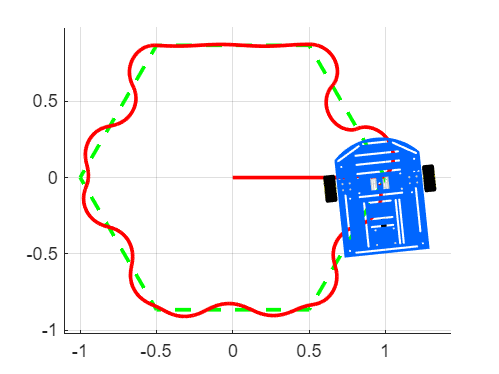


% Animación
figure('Name','Animación 1');
scale = 4;
MobileRobot_5;
H1 = MobilePlot_4(x(1), y(1), theta(1), scale); hold on;
plot(xd, yd, 'g--', 'LineWidth', 2); axis equal; grid on;
for k = 1:10:N
    delete(H1);
    H1 = MobilePlot_4(x(k), y(k), theta(k), scale);
    plot3(x_ctrl(1:k), y_ctrl(1:k), zeros(1,k), 'r', 'LineWidth', 2);
    pause(ts);
end

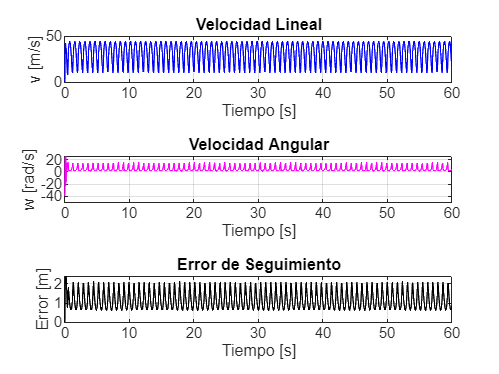

%% Trayectoria 2 - Flor 8 pétalos
clearvars -except ts tf t N
close all; clc;

ts = 0.05; tf = 60;
t = 0:ts:tf; N = length(t);

% Condiciones iniciales
x(1) = 0; y(1) = 0; theta(1) = pi/2;
x_ctrl(1) = x(1); y_ctrl(1) = y(1);

% Trayectoria polar r = a*sin(k*t)
a = 10; k_val = 4;
r = a * sin(k_val * t);
xd = r .* cos(t);
yd = r .* sin(t);

dr = a * k_val * cos(k_val * t);
xd_p = dr .* cos(t) - r .* sin(t);
yd_p = dr .* sin(t) + r .* cos(t);

% Ganancia
K = [5, 0; 0, 5];

% Simulación
for k = 1:N
    ex = xd(k) - x_ctrl(k);
    ey = yd(k) - y_ctrl(k);
    err(k) = sqrt(ex^2 + ey^2);

    J = [cos(theta(k)), -sin(theta(k)); sin(theta(k)), cos(theta(k))];
    q = pinv(J) * ([xd_p(k); yd_p(k)] + K * [ex; ey]);

    v(k) = q(1); w(k) = q(2);
    theta(k+1) = theta(k) + w(k)*ts;
    x(k+1) = x(k) + ts*v(k)*cos(theta(k));
    y(k+1) = y(k) + ts*v(k)*sin(theta(k));
    x_ctrl(k+1) = x(k+1); y_ctrl(k+1) = y(k+1);
end

% Gráficas
figure('Name','Trayectoria 2 - Flor');
tiledlayout(3,1)

nexttile; plot(t, v, 'b'); grid on;
xlabel('Tiempo [s]'); ylabel('v [m/s]');
title('Velocidad Lineal');

nexttile; plot(t, w, 'm'); grid on;
xlabel('Tiempo [s]'); ylabel('w [rad/s]');
title('Velocidad Angular');

nexttile; plot(t, err, 'k'); grid on;
xlabel('Tiempo [s]'); ylabel('Error [m]');
title('Error de Seguimiento');

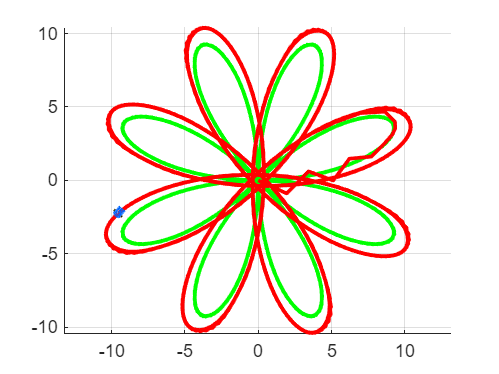


% Animación
figure('Name','Animación 2');
scale = 4;
MobileRobot_5;
H1 = MobilePlot_4(x(1), y(1), theta(1), scale); hold on;
plot(xd, yd, 'g--', 'LineWidth', 2); axis equal; grid on;
for k = 1:10:N
    delete(H1);
    H1 = MobilePlot_4(x(k), y(k), theta(k), scale);
    plot3(x_ctrl(1:k), y_ctrl(1:k), zeros(1,k), 'r', 'LineWidth', 2);
    pause(ts);
end

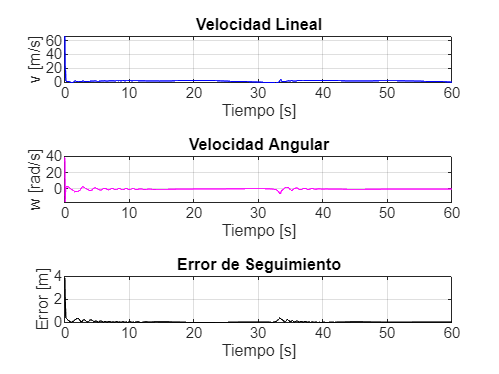

%% Trayectoria 3 - Corazón
clearvars -except ts tf t N
close all; clc;

ts = 0.05; tf = 60;
t = 0:ts:tf; N = length(t);

% Condiciones iniciales
x(1) = 0; y(1) = 0; theta(1) = pi/3;
x_ctrl(1) = x(1); y_ctrl(1) = y(1);

% Trayectoria con forma de corazón
t_scaled = linspace(0, 2*pi, length(t));
x_raw = 16 * sin(t_scaled).^3;
y_raw = 13*cos(t_scaled) - 5*cos(2*t_scaled) - 2*cos(3*t_scaled) - cos(4*t_scaled);

xd = (15/16) * x_raw;
yd = (13/17) * y_raw;

xd_p = [diff(xd)/ts, 0];
yd_p = [diff(yd)/ts, 0];

% Ganancia
K = [8, 0; 0, 20];

% Simulación
for k = 1:N
    ex = xd(k) - x_ctrl(k);
    ey = yd(k) - y_ctrl(k);
    err(k) = sqrt(ex^2 + ey^2);

    J = [cos(theta(k)), -sin(theta(k)); sin(theta(k)), cos(theta(k))];
    q = pinv(J) * ([xd_p(k); yd_p(k)] + K * [ex; ey]);

    v(k) = q(1); w(k) = q(2);
    theta(k+1) = theta(k) + w(k)*ts;
    x(k+1) = x(k) + ts*v(k)*cos(theta(k));
    y(k+1) = y(k) + ts*v(k)*sin(theta(k));
    x_ctrl(k+1) = x(k+1); y_ctrl(k+1) = y(k+1);
end

% Gráficas
figure('Name','Trayectoria 3 - Corazón');
tiledlayout(3,1)

nexttile; plot(t, v, 'b'); grid on;
xlabel('Tiempo [s]'); ylabel('v [m/s]');
title('Velocidad Lineal');

nexttile; plot(t, w, 'm'); grid on;
xlabel('Tiempo [s]'); ylabel('w [rad/s]');
title('Velocidad Angular');

nexttile; plot(t, err, 'k'); grid on;
xlabel('Tiempo [s]'); ylabel('Error [m]');
title('Error de Seguimiento');

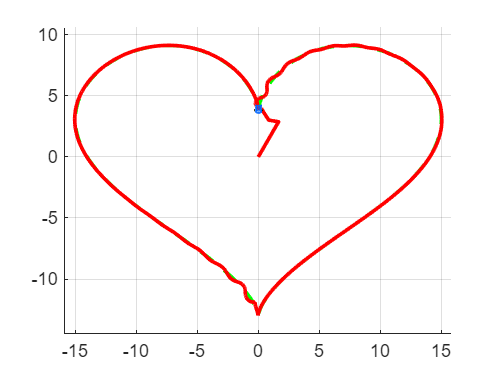


% Animación
figure('Name','Animación 3');
scale = 4;
MobileRobot_5;
H1 = MobilePlot_4(x(1), y(1), theta(1), scale); hold on;
plot(xd, yd, 'g--', 'LineWidth', 2); axis equal; grid on;
for k = 1:10:N
    delete(H1);
    H1 = MobilePlot_4(x(k), y(k), theta(k), scale);
    plot3(x_ctrl(1:k), y_ctrl(1:k), zeros(1,k), 'r', 'LineWidth', 2);
    pause(ts);
end